clear
clc


%  BE 6 COAST-DOWN VALIDATION (F0 / F2)


%% 1. BE 6 VEHICLE PARAMETERS (LOCKED BASELINE)

% Mass
M = 2415;                 % kg (BE6 estimated test mass)

% Dimensions
W = 1.907;                % m
H = 1.627;                % m
k = 0.84;                 % shape factor
Af = W * H * k;           % frontal area (m^2)

% Tire: 245/55R19
tire_width_mm = 245;
aspect_ratio  = 55;
wheel_dia_in  = 19;

sidewall_m = (tire_width_mm * aspect_ratio/100) / 1000;
wheel_radius_m = (wheel_dia_in * 0.0254) / 2;
tire_radius_m  = wheel_radius_m + sidewall_m;

% Environment (India – warm)
rho = 1.18;               % kg/m^3

% Assumed coefficients (can be tuned later)
Cr = 0.0125;              % rolling resistance (SUV tire)
Cd = 0.30;                % drag coefficient (EV SUV)

%% 2. ROAD-LOAD COEFFICIENTS (PHYSICS)

F0 = M * 9.81 * Cr;               % N
F1 = 0;                            % N/(m/s)
F2 = 0.5 * rho * Cd * Af;          % N/(m/s)^2

fprintf('\n--- BE6 Assumed Road Load ---\n');


--- BE6 Assumed Road Load ---


fprintf('F0 = %.2f N\n', F0);

F0 = 296.14 N


fprintf('F2 = %.4f N/(m/s)^2\n', F2);

F2 = 0.4613 N/(m/s)^2



%% 3. COAST-DOWN TEST INPUTS

T_drive = 0;                       % Nm (no drive torque)
slope   = 0;                       % %
xdot_o  = 120/3.6;                 % m/s (120 km/h start speed)

%% 4. RUN SIMULINK COAST-DOWN MODEL

mdl = 'LogitudinalVehicle_model';   % your Simulink model name
load_system(mdl)
tf=200;
out = sim(mdl);

%% 5. EXTRACT VELOCITY

v_sig = logsout.get('v (m/s)');
v = v_sig.Values.Data;
t = v_sig.Values.Time;

%% 6. IDENTIFY F0 / F2 FROM COAST-DOWN

% Numerical derivative
dvdt = gradient(v, t);          % m/s^2

% Measured resisting force from dynamics
F_meas = -M * dvdt;             % N

% Use clean speed window (avoid noise)
mask = (v > 5) & (v < 35);       % 18–126 km/h

X = [ones(sum(mask),1), v(mask).^2];
Y = F_meas(mask);

theta = X \ Y;                  % least-squares fit

F0_hat = theta(1);
F2_hat = theta(2);

fprintf('\n--- IDENTIFIED FROM COAST-DOWN ---\n');


--- IDENTIFIED FROM COAST-DOWN ---


fprintf('Identified F0 = %.2f N\n', F0_hat);

Identified F0 = 296.68 N


fprintf('Identified F2 = %.4f N/(m/s)^2\n', F2_hat);

Identified F2 = 0.4596 N/(m/s)^2



fprintf('\n--- ERROR ---\n');


--- ERROR ---


fprintf('F0 error = %.2f %%\n', 100*(F0_hat - F0)/F0);

F0 error = 0.18 %


fprintf('F2 error = %.2f %%\n', 100*(F2_hat - F2)/F2);

F2 error = -0.37 %


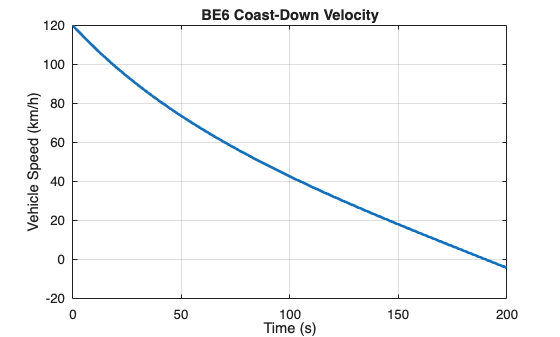


%% 7. PLOTS (VALIDATION)

% Velocity vs time
figure
plot(t, v*3.6, 'LineWidth',2)
xlabel('Time (s)')
ylabel('Vehicle Speed (km/h)')
title('BE6 Coast-Down Velocity')
grid on

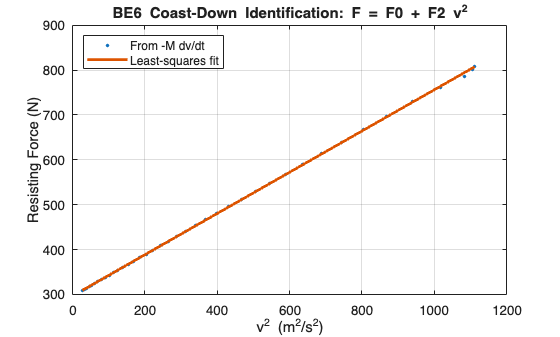


% Force vs v^2 (identification quality)
figure
plot(v(mask).^2, Y, '.', 'MarkerSize',8); hold on
plot(v(mask).^2, X*theta, 'LineWidth',2);
xlabel('v^2 (m^2/s^2)')
ylabel('Resisting Force (N)')
title('BE6 Coast-Down Identification: F = F0 + F2 v^2')
legend('From -M dv/dt','Least-squares fit','Location','northwest')
grid on


%% 8. SUMMARY PRINT

fprintf('\n--- SUMMARY ---\n');


--- SUMMARY ---


fprintf('Assumed : F0 = %.2f N,  F2 = %.4f\n', F0, F2);

Assumed : F0 = 296.14 N,  F2 = 0.4613


fprintf('Identified: F0 = %.2f N,  F2 = %.4f\n', F0_hat, F2_hat);

Identified: F0 = 296.68 N,  F2 = 0.4596
